folder_name = 'truncated_1'

folder_name = 'truncated_1'


p = 'orig';
file = strcat('data\', folder_name, '\',p,'Pc.csv')

file = 'data\truncated_1\origPc.csv'

table = readtable(file);

table = sortrows(table,1);

x = table.Var1;
y = table.Var2;
z = table.Var3;
u = table.Var4;
v = table.Var5;
w = table.Var6;

## Run through matched filter

mf_outputs = zeros(size(table,1), 1);
scores = zeros(size(table,1),1)

scores =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



template = [1 1 0];
template = template/norm(template);
length_template = length(template);

for i=1:size(table,1)
    signal = [u(i) v(i) w(i)];
    length_signal = length(signal);
    mf_output = dot(signal, template);
    mf_outputs(i) = mf_output;
    scores(i) = signal(1)/(sqrt(signal(2)^2 + signal(3)^2));
end


% r = zeros(size(x, 1),1);
% 
% for i = min(pc.XLimits)-1:incx:max(pc.XLimits)
%     for j = min(pc.YLimits)-1:incy:max(pc.YLimits)
%         for k = min(pc.ZLimits)-1:incz:max(pc.ZLimits)
%             indices = x>i & x<=i+incx & y>j & y<=j+incy & z>k & z<=k+incz;
%             r(indices) = index;
%             index = index + 1;
%         end
%     end
% end

score_colors = zeros(length(scores),1);
% c = linspace(1,3,length(scores));
% cmap = jet(3);
for i=1:length(scores)
    if scores(i) < 0.05
        score_colors(i) = 1;
    elseif scores(i) < 0.35
        score_colors(i) = 2;
    else
        score_colors(i) = 4;
    end
end

figure()
map = scatter3(x,y,z,10,score_colors,'filled')

map =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [0.8752 0.9989 1.2550 1.3179 1.5622 1.7017 4.6356 5.5433 7.1180 9.9213 9.9504 9.9579 9.9645 9.9733 9.9744 9.9852 9.9876 9.9918 10.0129 10.0142 10.0240 10.0252 10.0260 10.0265 10.0297 10.0323 10.0346 10.0373 10.0423 10.0441 … ]
              YData: [0.0704 0.0132 -0.6538 0.1584 -0.8754 -1.0011 -1.6699 0.4891 0.1027 -1.8547 0.2249 0.3842 -1.1310 -0.2918 -0.2520 -1.7023 -0.2125 0.9863 -0.7335 -0.0533 -1.2594 -0.1733 1.6818 0.5070 0.6678 -1.7928 -1.6284 0.1869 -2.4221 1.1941 … ]
              ZData: [0.0796 0.1227 -0.1008 0.1014 0.0980 0.1604 0.3728 0.3876 -0.3481 -1.7139 -1.7187 -1.7201 -1.7213 -1.7227 -1.7229 -1.7249 -1.7252 -1.7260 -1.7296 -1.7298 -1.7316 -1.7317 -1.7320 -1.7319 -1.7325 -1.7331 -1.7334 -1.7337 -1.7349 … ]
         


c = colorbar;
c.Ticks = [1,2,4];
c.TickLabels = {'Low Score','','High Score'};

c

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 4]
    FontSize: 9
    Position: [0.8338 0.1100 0.0381 0.8150]
       Units: 'normalized'

  Show all properties


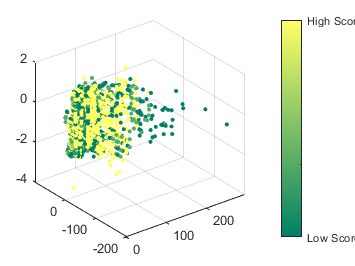

% colorbar
colormap summer
saveas(gcf,strcat('figures\',folder_name,'\scatterplot_score.png'))


temp_str_arr = string(template);
temp_str = "";
for i=1:length(temp_str_arr)
    temp_str = strcat(temp_str, '_', temp_str_arr(i))
end

temp_str = "_0.70711"

temp_str = "_0.70711_0.70711"

temp_str = "_0.70711_0.70711_0"

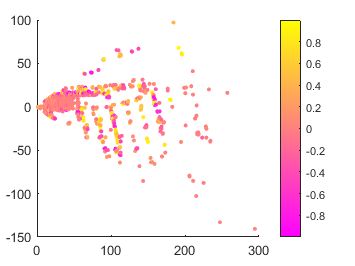


scatter(x,y,10,mf_outputs,'filled')
colormap spring
colorbar
saveas(gcf, strcat('figures\', folder_name, '\mf_outputs_xy_',p,temp_str,'.png'));

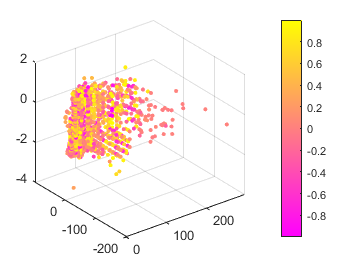

scatter3(x,y,z,10,mf_outputs,'filled')
colormap spring
colorbar
saveas(gcf, strcat('figures\', folder_name, '\mf_outputs_xyz_',p,temp_str,'.png'));

writematrix(mf_outputs,strcat('data\', folder_name, '\mf_outputs_',p,temp_str,'.csv'));

% scatter3(x,y,z,'.')
% T = delaunay(x,y)
% trimesh(T,x,y,z,"FaceAlpha", 0)
% saveas(gcf,strcat('figures\',folder_name,'\scatterplot_mesh.png'))

% %% Making Surface Plots From Scatter Data
% % How do you turn a collection of XYZ triplets into a surface plot? This is
% % the most frequently asked 3D plotting question that I got when I was in
% % Tech Support.
% %% Load the data
% load seamount
% who -file seamount
% %%
% % The problem is that the data is made up of individual (x,y,z)
% % measurements. It isn't laid out on a rectilinear grid, which is what the
% % SURF command expects. A simple plot command isn't very useful.
% plot3(x,y,z,'.-')
% %% Little triangles
% % The solution is to use Delaunay triangulation. Let's look at some
% % info about the "tri" variable.
% tri = delaunay(x,y);
% plot(x,y,'.')
% %%
% % How many triangles are there?
% [r,c] = size(tri);
% disp(r)
% %% Plot it with TRISURF
% h = trisurf(tri, x, y, z);
% axis vis3d
% %% Clean it up
% axis off
% l = light('Position',[-50 -15 29])
% set(gca,'CameraPosition',[208 -50 7687])
% lighting phong
% shading interp
% colorbar EastOutside